# Simple supported Euler-Bernoulli beam

Some examples for the function `getEulerBernoulliFunction.mlx `and `getEulerBernoulliSolutionWithNSupports.mlx`

## Verification with formulas from literature

Reference for verification:

Beate Bender, Dietmar Göhlich; Dubbel Taschenbuch für den Maschinenbau 1: Grundlagen und Tabellen; 26. Auflage; [https://doi.org/10.1007/978-3-662-59711-8;](https://doi.org/10.1007/978-3-662-59711-8;) 2020.

syms x F d_F L E I

### Equation in reference 

(Note: Displacement coordinate points downwards in the reference)


$$w(x) = \begin{cases} 
     w(x) = - \frac{F d_F (L-d_F)^2}{6 E I} \left[ \left(1+ \frac{L}{L-d_F} \right) \frac{x}{L} - \frac{x^3}{d_F(L-d_F)L} \right] & 
          0\leq x\leq d_F \\
     w(x) = - \frac{F {d_F}^2 (L-d_F)}{6 E I} \left[ \left(1+ \frac{L}{d_F} \right) \frac{L-x}{L} - \frac{(L-x)^3}{d_F(L-d_F)L} \right] &  d_F \leq x\leq L
       \end{cases}$$


w_pw_lit=[-(F.*d_F .*(L-d_F).^2)./(6.*E.*I).*((1+L./(L-d_F)).*x./L - x.^3./(d_F.*(L-d_F).*L)); ...
       -(F.*d_F.^2 .*(L-d_F))./(6.*E.*I).*((1+L./d_F).*(L-x)./L - (L-x).^3./(d_F.*(L-d_F).*L))];
w_pw_lit=simplify(w_pw_lit)

$$w\_pw\_lit = \left(\begin{array}{c} \frac{F\,x\,\left(L-d_{F}\right)\,\left({d_{F}}^{2}-2\,L\,d_{F}+x^{2}\right)}{6\,\text{E}\,\text{I}\,L}\\ \frac{F\,d_{F}\,\left(L-x\right)\,\left({d_{F}}^{2}+x^{2}-2\,L\,x\right)}{6\,\text{E}\,\text{I}\,L} \end{array}\right)$$

cond_lit=[0<= x & x<= d_F; d_F< x & x<= L];

dw_pw_lit=simplify(diff(w_pw_lit,x))

$$dw\_pw\_lit = \left(\begin{array}{c} \frac{F\,\left(L-d_{F}\right)\,\left({d_{F}}^{2}-2\,L\,d_{F}+3\,x^{2}\right)}{6\,\text{E}\,\text{I}\,L}\\ -\frac{F\,d_{F}\,\left(2\,L^{2}-6\,L\,x+{d_{F}}^{2}+3\,x^{2}\right)}{6\,\text{E}\,\text{I}\,L} \end{array}\right)$$

ddw_pw_lit=simplify(diff(dw_pw_lit,x))

$$ddw\_pw\_lit = \left(\begin{array}{c} \frac{F\,x\,\left(L-d_{F}\right)}{\text{E}\,\text{I}\,L}\\ \frac{F\,d_{F}\,\left(L-x\right)}{\text{E}\,\text{I}\,L} \end{array}\right)$$

### Equation from matlab function `getEulerBernoulliFunction`

[~,~,~,~,~,~,~,~,~,~,~,...
     w_pw,dw_pw,ddw_pw,~,~,cond] =...
     getEulerBernoulliFunction(d_F,F,E,I,{0 L});
w_pw(x)=[w_pw(1);w_pw(2)]

$$w\_pw(x) = \left(\begin{array}{c} \frac{F\,x\,\left(L-d_{F}\right)\,\left({d_{F}}^{2}-2\,L\,d_{F}+x^{2}\right)}{6\,\text{E}\,\text{I}\,L}\\ \frac{F\,d_{F}\,\left(L-x\right)\,\left({d_{F}}^{2}+x^{2}-2\,L\,x\right)}{6\,\text{E}\,\text{I}\,L} \end{array}\right)$$

dw_pw(x)=[dw_pw(1);dw_pw(2)]

$$dw\_pw(x) = \left(\begin{array}{c} \frac{F\,\left(L-d_{F}\right)\,\left({d_{F}}^{2}-2\,L\,d_{F}+3\,x^{2}\right)}{6\,\text{E}\,\text{I}\,L}\\ -\frac{F\,d_{F}\,\left(2\,L^{2}-6\,L\,x+{d_{F}}^{2}+3\,x^{2}\right)}{6\,\text{E}\,\text{I}\,L} \end{array}\right)$$

ddw_pw(x)=[ddw_pw(1);ddw_pw(2)]

$$ddw\_pw(x) = \left(\begin{array}{c} \frac{F\,x\,\left(L-d_{F}\right)}{\text{E}\,\text{I}\,L}\\ \frac{F\,d_{F}\,\left(L-x\right)}{\text{E}\,\text{I}\,L} \end{array}\right)$$

cond=[cond(1);cond(2)];

### Verification

Difference between reference equation and matlab equation should be zero.

Displacement

w_pw-w_pw_lit

$$ans(x) = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Inclination

dw_pw-dw_pw_lit

$$ans(x) = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

Curvature

ddw_pw-ddw_pw_lit

$$ans(x) = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

### Example

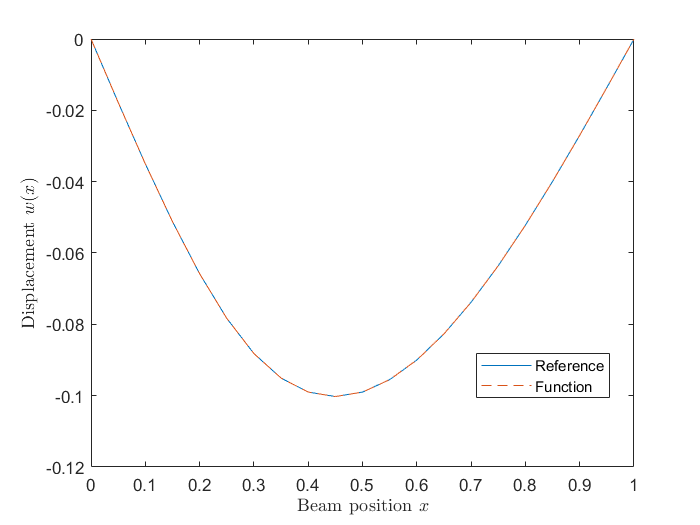

F_val=6; d_F_val=0.3;
I_val=1; E_val=1; 
L_val=1;
numOfPnts=21;
x_val=(0:(numOfPnts-1))/(numOfPnts-1)*L_val;

vars=[F      d_F      I      E      L      x];
vals={F_val  d_F_val  I_val  E_val  L_val  x_val};

w_pw_lit_subs=double(subs(w_pw_lit,vars,vals));
cond_lit_sub=boolean(subs(cond_lit,vars,vals));
w_lit_subs=sum(w_pw_lit_subs.*cond_lit_sub,1);

w_pw=double(subs(w_pw,vars,vals));
cond_sub=boolean(subs(cond,vars,vals));
w_subs=sum(w_pw.*cond_sub,1);

figure
hold on;
plot(x_val,w_lit_subs)
plot(x_val,w_subs,'--')
legend('Reference','Function','Location','best')
xlabel('Beam position $x$','Interpreter','latex')
ylabel('Displacement $w(x)$','Interpreter','latex')
box on

Mean square error for displacement

sum((w_lit_subs-w_subs).^2)

ans = 0

clearvars

## Simple supported beam

With four derivaties of displacement

### One field

without middle support

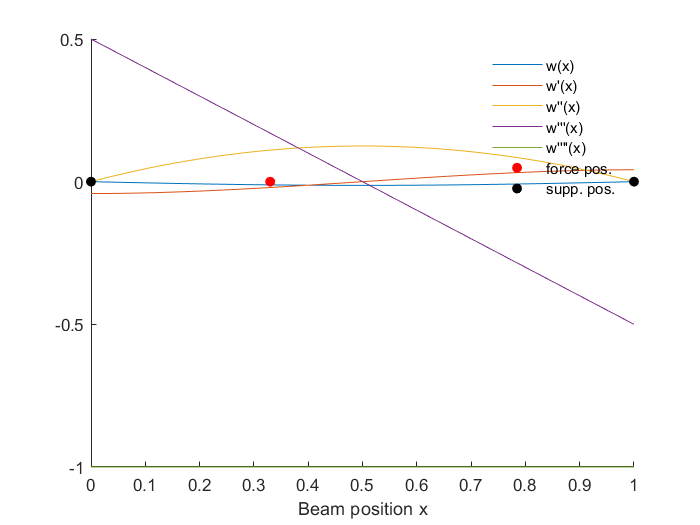

d_F=0.33; % force position in m
L=1; % bridge length
s=[0 L]; % support positions in m
F=6; % force in N
E=1; % elastic modulus in N/m^2
I=1; % second moment of area
[wFun,dwFun,ddwFun,dddwFun,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s);

x=0:.01:1; % Beam positions

    w=arrayfun(@(x)     wFun(x),x); % displacement
   dw=arrayfun(@(x)    dwFun(x),x); % 
  ddw=arrayfun(@(x)   ddwFun(x),x);
 dddw=arrayfun(@(x)  dddwFun(x),x);
ddddw=arrayfun(@(x) ddddwFun(x),x);

figure
hold on
plot(x,    w)
plot(x,   dw)
plot(x,  ddw)
plot(x, dddw)
plot(x,ddddw)
scatter(d_F,0,'r','filled')
scatter(s,0,'k','filled')
xlabel('Beam position x')
legend("w(x)", "w'(x)", "w''(x)", "w'''(x)", "w''''(x)","force pos.","supp. pos.",...
    'box','off')

### Two fields

With one middle support

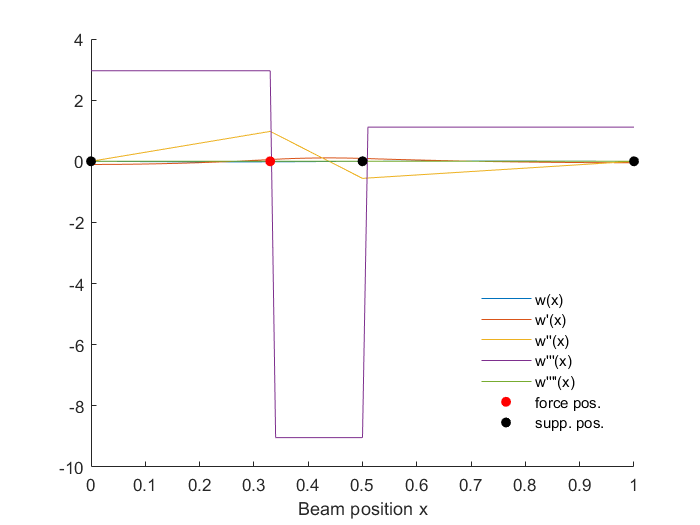

% d_F=0.25; % force position in m
s_m=0.5; % middle support position in m
L=1; % bridge length in m
s=[0 s_m L]; % support positions
F=12; % force in N
E=1; % elastic modulus in N/m^2
I=1; %second moment of area
[wFun,dwFun,ddwFun,dddwFun,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s);

x=0:.01:L; % beam positions

    w=arrayfun(@(x)     wFun(x),x);
   dw=arrayfun(@(x)    dwFun(x),x);
  ddw=arrayfun(@(x)   ddwFun(x),x);
 dddw=arrayfun(@(x)  dddwFun(x),x);
ddddw=arrayfun(@(x) ddddwFun(x),x);

figure
hold on
plot(x,    w)
plot(x,   dw)
plot(x,  ddw)
plot(x, dddw)
plot(x,ddddw)
scatter(d_F,0,'r','filled')
scatter(s,0,'k','filled')
xlabel('Beam position x')
legend("w(x)", "w'(x)", "w''(x)", "w'''(x)", "w''''(x)","force pos.","supp. pos.",...
    'box','off','Location','best')

### Three fields

With 2 middle supports

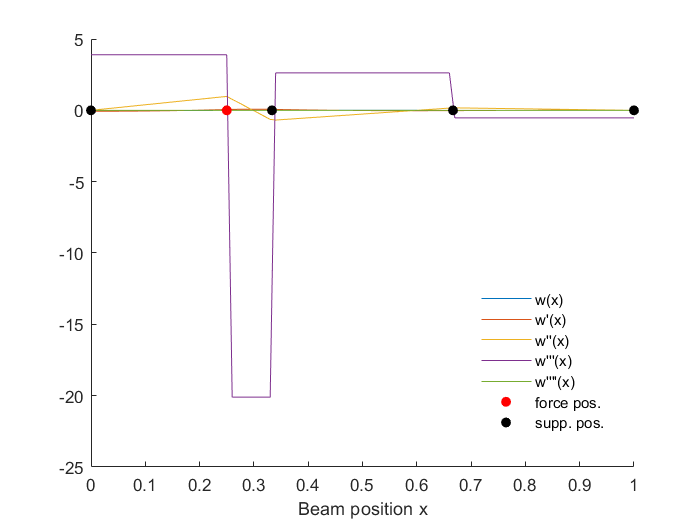

d_F=0.25; % force position in m
s_m1=1/3; % left middle support position in m
s_m2=2/3; % right middle support position in m
L=1; % bridge length in m
s=[0 s_m1 s_m2 L]; % support positions
F=24; % force in N
E=1; % elastic modulus in N/m^2
I=1; %second moment of area
[wFun,dwFun,ddwFun,dddwFun,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s);

x=0:.01:L; % beam positions

    w=arrayfun(@(x)     wFun(x),x);
   dw=arrayfun(@(x)    dwFun(x),x);
  ddw=arrayfun(@(x)   ddwFun(x),x);
 dddw=arrayfun(@(x)  dddwFun(x),x);
ddddw=arrayfun(@(x) ddddwFun(x),x);

figure
hold on
plot(x,    w)
plot(x,   dw)
plot(x,  ddw)
plot(x, dddw)
plot(x,ddddw)
scatter(d_F,0,'r','filled')
scatter(s,0,'k','filled')
xlabel('Beam position x')
legend("w(x)", "w'(x)", "w''(x)", "w'''(x)", "w''''(x)","force pos.","supp. pos.",...
    'box','off','Location','best')

clearvars

## Moving middle support for 3 support beam

force is applied in the middle left field

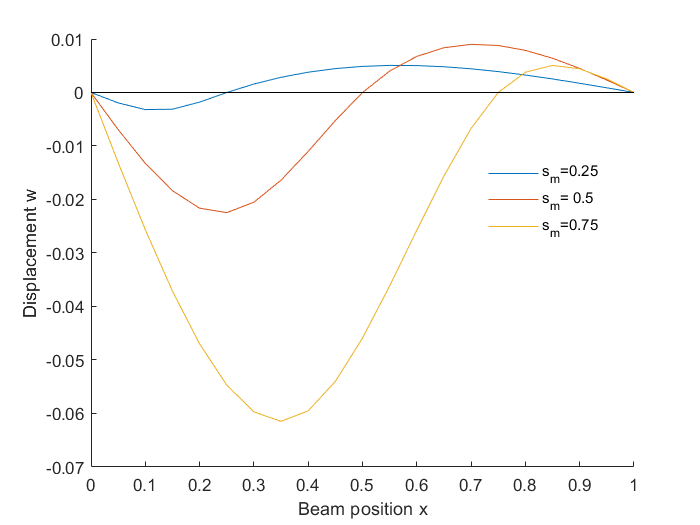

d_F=sym('d_F'); % force position
L=1;
s={0 sym('s_m') L}; % support positions
F=12; % force in N
E=1; % elastic modulus in N/m^2
I=1; % second moment of area in m^2
wFun = getEulerBernoulliFunction(d_F,F,E,I,s); % get dispclacement function for varying middle support

numOfPnts=21;
x=(0:(numOfPnts-1))/(numOfPnts-1)*L; % beam position
s_m=0.25:0.25:0.75; % multiple middle supports
[X,S_m]=meshgrid(x,s_m); 

D_F=repmat((s_m/2)',1,length(x));

w=arrayfun(@(x,d_F,s_m) wFun(x,d_F,s_m),X,D_F,S_m); 

figure
hold on
plot(x,w)
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'s_m='},num2str(s_m')),'location','best','Box','off')

clearvars

## Different number of supports

% force position d_F is in the middle of the first field
s1=[0                1]; % no middle support
s2=[0       .5       1]; % 1 middle support 
s3=[0    .33  .66    1]; % 2 middle support 
s4=[0 .25   .5   .75 1]; % 3 middle support 
F1= 6; % force for config. w/o middle support
F2=12; % force for config. w/ 1 middle support
F3=24; % force for config. w/ 2 middle supports
F4=48; % force for config. w/ 3 middle supports
E=1; % elastic modulus
I=1; % second moment of area
tic
wFun1 = getEulerBernoulliFunction(mean(s1(1:2)),F1,E,I,s1);
toc

Elapsed time is 0.752272 seconds.


tic
wFun2 = getEulerBernoulliFunction(mean(s2(1:2)),F2,E,I,s2);
toc

Elapsed time is 1.708881 seconds.


tic
wFun3 = getEulerBernoulliFunction(mean(s3(1:2)),F3,E,I,s3);
toc

Elapsed time is 4.023399 seconds.


tic
wFun4 = getEulerBernoulliFunction(mean(s4(1:2)),F4,E,I,s4);
toc

Elapsed time is 14.278038 seconds.


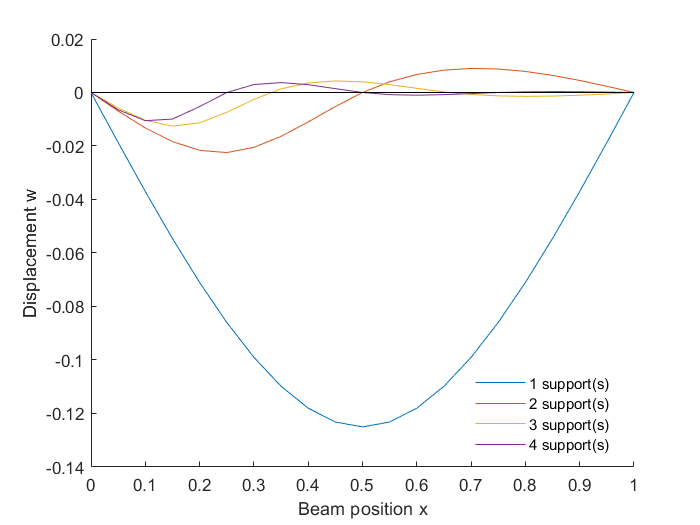


x=0:.05:1; % beam position

w1=arrayfun(@(x) wFun1(x),x); % displacement
w2=arrayfun(@(x) wFun2(x),x); % displacement
w3=arrayfun(@(x) wFun3(x),x); % displacement
w4=arrayfun(@(x) wFun4(x),x); % displacement

figure
hold on
plot(x,[w1' w2' w3' w4'])
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat(num2str((1:4)'),{' support(s)'}),'location','best','Box','off')

clearvars

## Moving force

Force moves from 0 to L

### One field

L=1;
s={0 L}; % support positions
F=6; % force
E=1; % elastic modulus
I=1; % second moment of area
d_F=[]; % force position
[wFun,~,ddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s); % get displacement and curvature

#### Beam displacement for fixed force - 1D

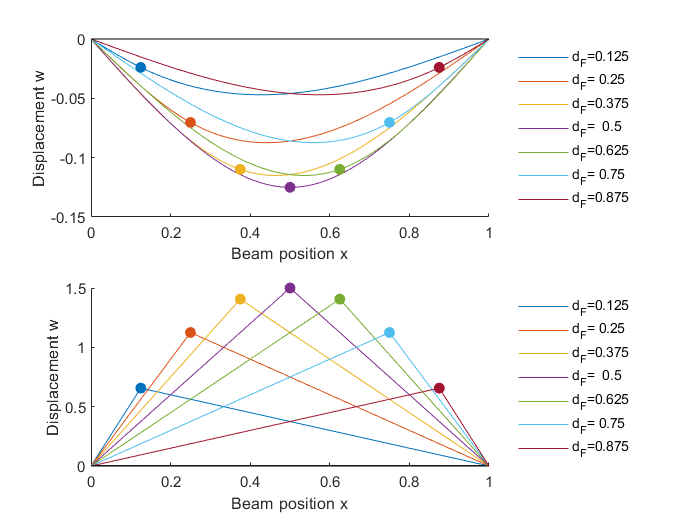

numOfSamples=7;
numOfBeamPos=201;
x=linspace(0,L,numOfBeamPos); % beam position
d_F=linspace(0,L,numOfSamples+2);
d_F([1 end])=[];

[D_F,X]=meshgrid(d_F,x);

w=arrayfun(@(x,d_F) wFun(x,d_F),X,D_F);
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),X,D_F);

figure
subplot(211)
hold on
p=plot(x,w);
for ii=1:length(p)
    idx=d_F(ii)==X;
    idx=find(idx);
    idx=idx(ii);
    scatter(d_F(ii),w(idx),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'d_F='},num2str(d_F')),'location','eastoutside','Box','off')
subplot(212)
hold on
p=plot(x,ddw);
for ii=1:length(p)
    idx=d_F(ii)==X;
    idx=find(idx);
    idx=idx(ii);
    scatter(d_F(ii),ddw(idx),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'d_F='},num2str(d_F')),'location','eastoutside','Box','off')

#### Displacement/Curvature at fixed reference position x - 1D

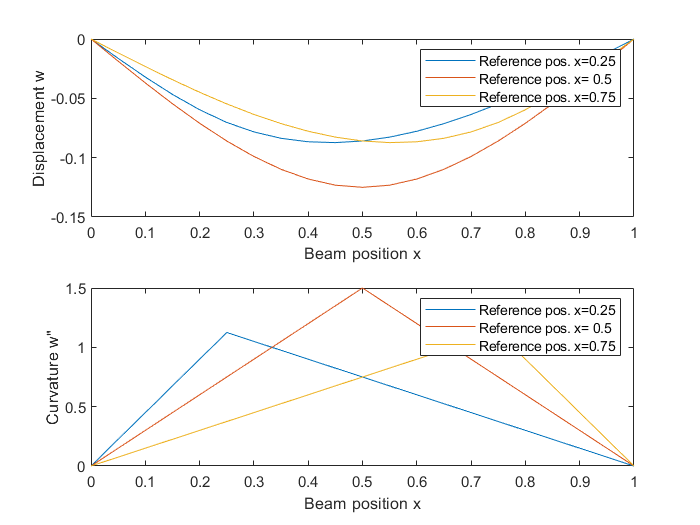

numOfSamples=21;
numOfBeamPos=3;
xRefPos=linspace(0,L,numOfBeamPos+2)';
xRefPos([1 end])=[];
d_F=linspace(0,L,numOfSamples);

[XRefPos,D_F]=meshgrid(xRefPos,d_F);

  w=arrayfun(@(x,d_F)   wFun(x,d_F),XRefPos,D_F);
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),XRefPos,D_F);

figure
subplot(211)
plot(d_F,w)
legend(strcat('Reference pos. x=',num2str(xRefPos)))
xlabel('Beam position x')
ylabel('Displacement w')
subplot(212)
plot(d_F,ddw)
legend(strcat('Reference pos. x=',num2str(xRefPos)))
xlabel('Beam position x')
ylabel('Curvature w"')

#### 2D visualisation

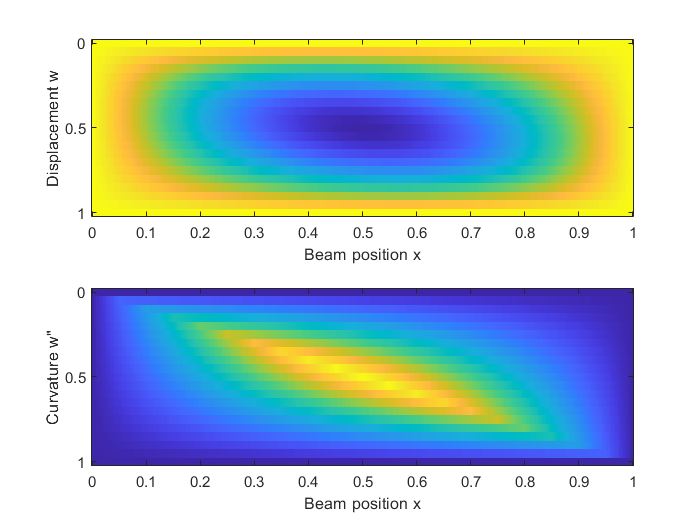

numOfSamples=21;
numOfBeamPos=201;
x=linspace(0,L,numOfBeamPos);
d_F=linspace(0,L,numOfSamples);
[X,D_F]=meshgrid(x,d_F);


  w=arrayfun(@(x,d_F)   wFun(x,d_F),X,D_F);
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),X,D_F);

figure
subplot(211)
imagesc(x,d_F,w)
xlabel('Beam position x')
ylabel('Displacement w')
subplot(212)
imagesc(x,d_F,ddw)
xlabel('Beam position x')
ylabel('Curvature w"')

### Two fields

s_m=0.5;
L=1;
s={0 s_m L}; % support positions
F=12; % force
E=1; % elastic modulus
I=1; % second moment of inertia
d_F=[]; % force position
[wFun,~,ddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s); % get function for displacment

numOfSamples=7;
numOfBeamPos=201;
x=linspace(0,L,numOfBeamPos); % beam position
d_F=linspace(0,L,numOfSamples+2);
d_F([1 end])=[];
[D_F,X]=meshgrid(d_F,x);

#### **Beam d**isplacement for fixed force - 1D

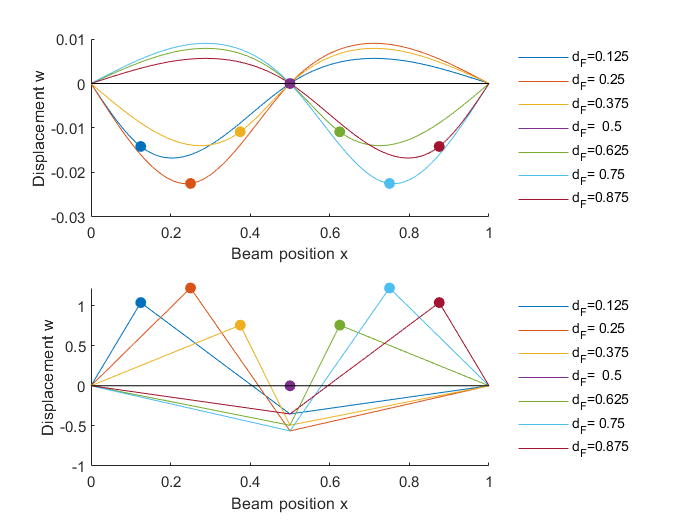

w=arrayfun(@(x,d_F) wFun(x,d_F),X,D_F); % displacement
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),X,D_F); % displacement

figure
subplot(211)
hold on
p=plot(x,w);
for ii=1:length(p)
    idx=d_F(ii)==X;
    idx=find(idx);
    idx=idx(ii);
    scatter(d_F(ii),w(idx),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'d_F='},num2str(d_F')),'location','eastoutside','Box','off')
subplot(212)
hold on
p=plot(x,ddw);
for ii=1:length(p)
    idx=d_F(ii)==X;
    idx=find(idx);
    idx=idx(ii);
    scatter(d_F(ii),ddw(idx),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'d_F='},num2str(d_F')),'location','eastoutside','Box','off')

#### Displacement/Curvature at fixed reference position x - 1D

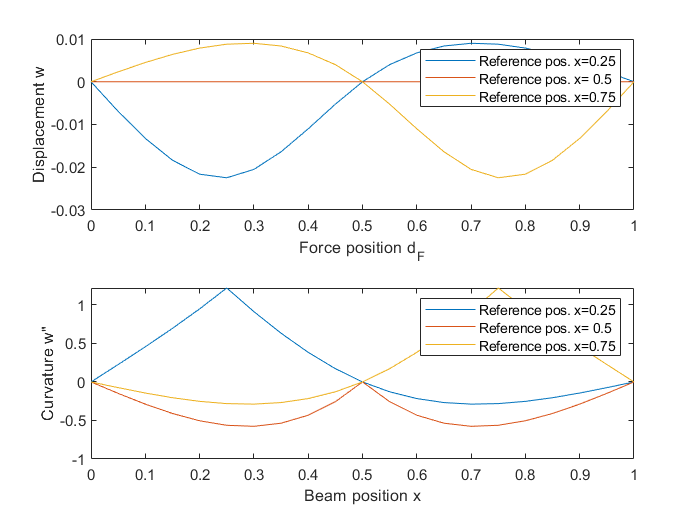

numOfSamples=21;
numOfBeamPos=3;
xRefPos=linspace(0,L,numOfBeamPos+2)';
xRefPos([1 end])=[];
d_F=linspace(0,L,numOfSamples);

[XRefPos,D_F]=meshgrid(xRefPos,d_F);

  w=arrayfun(@(x,d_F)   wFun(x,d_F),XRefPos,D_F);
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),XRefPos,D_F);

figure
subplot(211)
plot(d_F,w)
legend(strcat('Reference pos. x=',num2str(xRefPos)))
xlabel('Force position d_F')
ylabel('Displacement w')
subplot(212)
plot(d_F,ddw)
legend(strcat('Reference pos. x=',num2str(xRefPos)))
xlabel('Beam position x')
ylabel('Curvature w"')

#### 2D visualisation

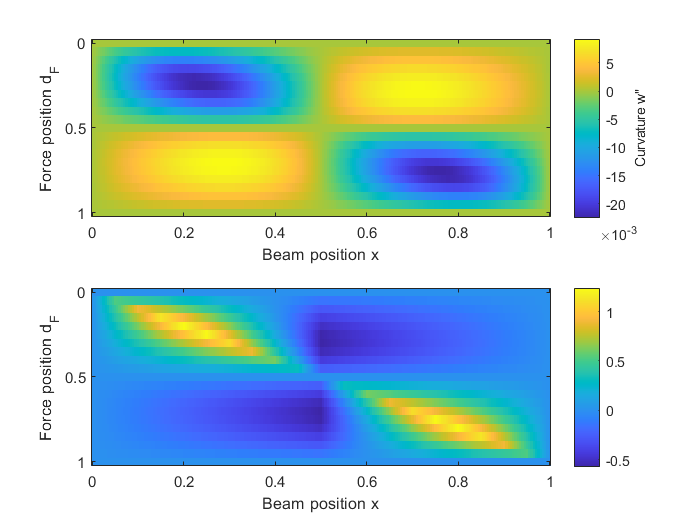

numOfSamples=21;
numOfBeamPos=201;
xRefPos=linspace(0,L,numOfBeamPos+2)';
xRefPos([1 end])=[];
d_F=linspace(0,L,numOfSamples);
[X,D_F]=meshgrid(x,d_F);


  w=arrayfun(@(x,d_F)   wFun(x,d_F),X,D_F);
ddw=arrayfun(@(x,d_F) ddwFun(x,d_F),X,D_F);

figure
subplot(211)
imagesc(x,d_F,w)
xlabel('Beam position x')
ylabel('Force position d_F')
c=colorbar;
c.Label.String='Curvature w"';
subplot(212)
imagesc(x,d_F,ddw)
xlabel('Beam position x')
ylabel('Force position d_F')
c=colorbar;
c.Label.String='Curvature w"';
c=colorbar;

clearvars

## Three moving forces

### One field

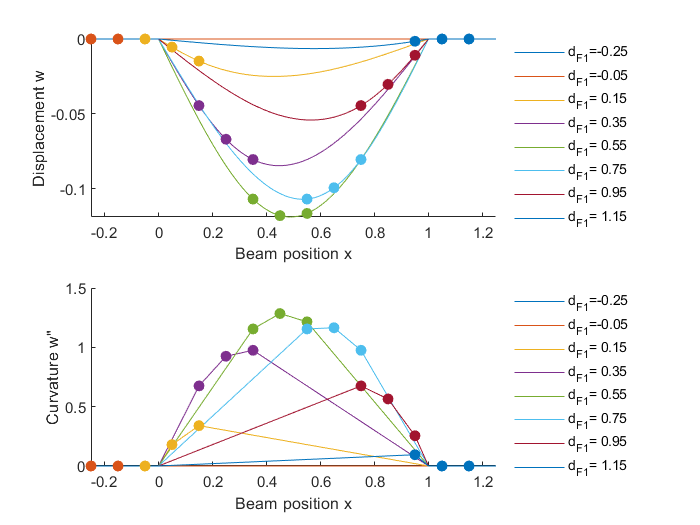

s=[0 1]; % support positions
F=2; % force
E=1; % elastic modulus
I=1; % second moment of area
d_F=[]; % force position
[wFun,~,ddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s); % get displ. + curv.
forcePos=[0 -.1 -.2]; % force distances

startPoint=-0.25; % starting position
endPoint  = 1.25; % end position
steps     = .01; % 

x=startPoint:steps:endPoint; % beam position
d_F=startPoint:20*steps:endPoint; % force position

% expand one force to multiple forces
d_F=repmat(d_F,1,1,length(forcePos));

for ii=1:length(forcePos)
    d_F(:,:,ii)=d_F(:,:,ii) + forcePos(ii);
end

% meshgrid for each constellation
D_F=zeros(length(x),length(d_F),length(forcePos));
X  =zeros(length(x),length(d_F),length(forcePos));
W  =zeros(length(x),length(d_F),length(forcePos));
ddW=zeros(length(x),length(d_F),length(forcePos));
for ii=1:length(forcePos)
    [D_F(:,:,ii),X(:,:,ii)]=meshgrid(d_F(:,:,ii),x);
end

% calc displacement for each for each constellation
for ii=1:numel(W)
    W(ii) = wFun(X(ii),D_F(ii));
    ddW(ii) = ddwFun(X(ii),D_F(ii));
end

% superposition
w=sum(W,3);
ddw=sum(ddW,3);

figure
subplot(211)
hold on
p=plot(x,w);
for ii=1:length(p)
    
    ii_forcePos=squeeze(d_F(1,ii,:));
    
    idx=abs(ii_forcePos-x) <=3*eps;
    [~,idx]=find(idx);
    
    ii_forcePos=sort(ii_forcePos(1:numel(idx)));
    
    scatter(ii_forcePos,w(idx,ii),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
% plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Displacement w')
legend(strcat({'d_F_1='},num2str(d_F(:,:,1)')),'location','eastoutside','Box','off')
xlim([min(x) max(x)])
subplot(212)
hold on
p=plot(x,ddw);
for ii=1:length(p)
    
    ii_forcePos=squeeze(d_F(1,ii,:));
    
    idx=abs(ii_forcePos-x) <=3*eps;
    [~,idx]=find(idx);
    
    ii_forcePos=sort(ii_forcePos(1:numel(idx)));
    
    scatter(ii_forcePos,ddw(idx,ii),...
        'MarkerEdgeColor',p(ii).Color,...
        'MarkerFaceColor',p(ii).Color)
end
% plot(xlim,[0 0],'k')
xlabel('Beam position x')
ylabel('Curvature w"')
legend(strcat({'d_F_1='},num2str(d_F(:,:,1)')),'location','eastoutside','Box','off')
xlim([min(x) max(x)])

clearvars

## Distributed load

With four derivaties of displacement

### One field

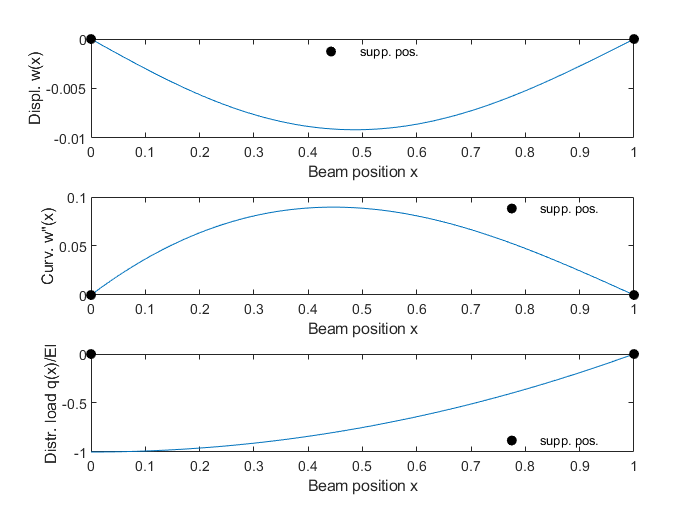

syms x

d_F=0.33; % force position in m
L=1; % bridge length
s=[0 L]; % support positions in m
F=0; % force in N
E=1; % elastic modulus in N/m^2
I=1; % second moment of area
q=x^2-1;
[wFun,~,ddwFun,~,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s,q);

x_val=0:.01:1; % Beam positions

    w=arrayfun(@(x)     wFun(x),x_val); % displacement
  ddw=arrayfun(@(x)   ddwFun(x),x_val); % curvature
ddddw=arrayfun(@(x) ddddwFun(x),x_val);

figure
subplot(311)
hold on
plot(x_val,    w)
scatter(s,0,'k','filled')
xlabel('Beam position x')
ylabel('Displ. w(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(312)
hold on
plot(x_val,  ddw)
scatter(s,0,'k','filled')
xlabel('Beam position x')
ylabel('Curv. w"(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(313)
hold on
plot(x_val,ddddw)
scatter(s,0,'k','filled')
xlabel('Beam position x')
ylabel('Distr. load q(x)/EI')
legend("","supp. pos.",...
    'box','off','Location','best')
box on

### Three fields

With 2 middle supports

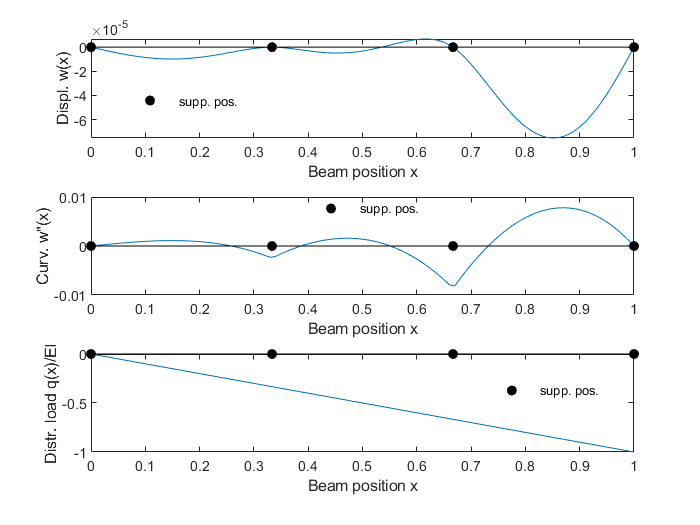

d_F=0.25; % force position in m
s_m1=1/3; % left middle support position in m
s_m2=2/3; % right middle support position in m
L=1; % bridge length in m
s=[0 s_m1 s_m2 L]; % support positions
F=0; % force in N
E=1; % elastic modulus in N/m^2
I=1; % second moment of area
q=-1*x;
[wFun,~,ddwFun,~,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s,q);

x_val=0:.01:1; % Beam positions

    w=arrayfun(@(x)     wFun(x),x_val); % displacement
  ddw=arrayfun(@(x)   ddwFun(x),x_val); % curvature
ddddw=arrayfun(@(x) ddddwFun(x),x_val);

figure
subplot(311)
hold on
plot(x_val,    w)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Displ. w(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(312)
hold on
plot(x_val,  ddw)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Curv. w"(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(313)
hold on
plot(x_val,ddddw)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Distr. load q(x)/EI')
legend("","supp. pos.",...
    'box','off','Location','best')
box on

### Five fields

With 2 middle supports

d_F=0.25; % force position in m
s_m1=0.1; % left outer support position in m
s_m2=0.2; % left inner support position in m
s_m3=0.8; % right middle support position in m
s_m4=0.9; % right middle support position in m
L=1; % bridge length in m
s=[0 s_m1 s_m2 s_m3 s_m4 L]; % support positions
F=0; % force in N
E=1; % elastic modulus in N/m^2
I=1; % second moment of area
q=-1;
tic
[wFun,~,ddwFun,~,ddddwFun] = getEulerBernoulliFunction(d_F,F,E,I,s,q);
toc

Elapsed time is 118.457629 seconds.


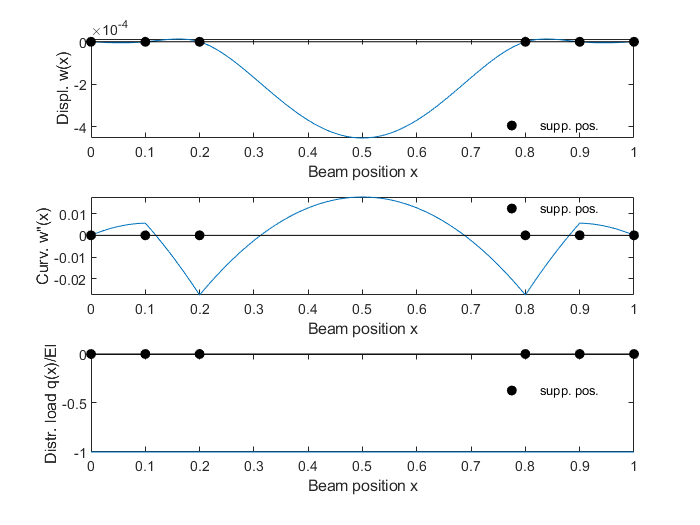


x_val=0:.01:1; % Beam positions

    w=arrayfun(@(x)     wFun(x),x_val); % displacement
  ddw=arrayfun(@(x)   ddwFun(x),x_val); % curvature
ddddw=arrayfun(@(x) ddddwFun(x),x_val);

figure
subplot(311)
hold on
plot(x_val,    w)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Displ. w(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(312)
hold on
plot(x_val,  ddw)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Curv. w"(x)')
legend("","supp. pos.",...
    'box','off','Location','best')
box on
%
subplot(313)
hold on
plot(x_val,ddddw)
scatter(s,0,'k','filled')
plot([0 L],[0 0],'k')
xlabel('Beam position x')
ylabel('Distr. load q(x)/EI')
legend("","supp. pos.",...
    'box','off','Location','best')
box on